# Exercise A | Beam analysis with the stiffness method

This lesson links the mechanics of a continuous beam to each step of a matrix-based MATLAB solution. Read the explanation, inspect the code, and then run the section. Use Run All for the complete solution, or run the sections in order: later sections reuse variables created earlier.

Problem: a 10 m continuous beam has fixed ends at x = 0 and 10 m and a roller at x = 6 m. A 25 kN point force acts downward at x = 3 m; a 15 kN/m uniform load acts downward over the 4 m right span. Determine the end support moments. The common EI is unspecified.

Model assumptions: straight prismatic Euler-Bernoulli beam, linear elastic material, small displacements and rotations, and negligible shear deformation. The beam remains continuous over the roller. Units throughout the calculation are kN, m, and radians.

The code is runnable without additional files or toolboxes. Output tables and response plots are generated when you run it; there are no stored execution outputs in this source file.

## 1. Start with a clean workspace

clear removes variables left by previous analyses; clc clears the Command Window; close all closes existing figures. This makes a complete run reproducible. format short g changes the displayed number format without changing calculation accuracy.

Run this first section once at the start. Running it again halfway through the lesson removes the matrices and vectors needed by the remaining sections.

clear; clc; close all;
format short g;

## 2. Translate the beam into numerical input

xNode gives the global position of each support. Each row of connectivity contains the left and right node numbers of one element. Two elements are sufficient: one for each span. The point force in Exercise A is represented inside its span by a consistent load vector, so it does not require an extra node.

q stores the uniform transverse load on each element; P stores an optional interior point force; a measures that force location from the element's left end. Downward loads are negative. EI is flexural rigidity, not Young's modulus alone.

Why can we use EI = 1? With one common EI and zero imposed support movements, K = EI K_0 and the unknown displacement scales as 1/EI. Consequently the product Kd, reactions, and internal moments do not depend on the numerical value chosen for EI. The raw rotations and deflections calculated using this reference value are not physical displacement predictions.


$$\mathbf{K}=EI\,\mathbf{K}_0,\qquad \mathbf{d}\propto\frac{1}{EI},\qquad \mathbf{R}\ \mathrm{independent\ of}\ EI$$


The deflection diagram therefore shows EI*v. Divide its values by the actual EI, in kN m^2, to recover displacement in metres. The reference moment vector is used only to check the original exercise.

 Because every element has the SAME EI and there are no support movements, the common EI cancels from the force solution. A reference EI=1 is valid for finding reactions and moments. It is NOT a measured beam stiffness. The reference rotations/deflections are not physical numerical predictions.Enter an actual common EI here if physical displacements are required.

## 3. Number the degrees of freedom

A bending-only beam node has two degrees of freedom: vertical displacement v and rotation $\theta$ = dv/dx. Three nodes therefore create six global unknown positions, even though some values will be prescribed by supports. Axial displacement is outside the present bending model.


$$\mathbf{d}=\pmatrix{v_1&\theta_1&v_2&\theta_2&v_3&\theta_3}^{T}$$


The index rule 2i-1 selects vertical displacement at node i; 2i selects rotation. elementDOF maps each local element vector into the global vector. Element 1 uses [1 2 3 4]; element 2 uses [3 4 5 6]. Shared indices 3 and 4 enforce continuity at the roller.

## 4. Apply the support constraints

At each fixed end, both displacement and rotation are prescribed as zero. At support 2 the roller prescribes vertical displacement, while rotation remains free. Thus freeDOF = 4: the only unknown nodal displacement is theta_2. prescribedDOF lists the remaining five entries.


$$\theta_1=\theta_3=v_1=v_3=0,\qquad v_2=0,\qquad \theta_2\ \mathrm{unknown}$$


A roller is not an internal hinge. It cannot supply an external reaction couple, but the continuous beam can carry a nonzero internal bending moment through that section. The two member end moments at the roller must balance.

## 5. Prepare the global arrays

K stores the assembled 6 x 6 stiffness matrix, F the six equivalent nodal loads, and d the six nodal displacement/rotation values. Rows 1, 3, and 5 correspond to vertical forces; rows 2, 4, and 6 correspond to moments. Their units differ, so a stiffness matrix must be interpreted together with its degree-of-freedom ordering.

elementK and elementLoad retain each element's original data for later force recovery. In MATLAB, zeros(4,4,nElement) allocates a stack of 4 x 4 matrices. L stores element lengths calculated from node coordinates.

## 6. Form and assemble element stiffness and loads

For a prismatic Euler-Bernoulli element, local displacement order is [v_i, theta_i, v_j, theta_j]. The stiffness matrix relates nodal displacements to nodal actions when span loading is handled separately. All beam elements lie along the same global axis, so no coordinate rotation matrix is needed.


$$\mathbf{k}_e=\frac{EI}{L^3}\pmatrix{12&6L&-12&6L\cr 6L&4L^2&-6L&2L^2\cr-12&-6L&12&-6L\cr6L&2L^2&-6L&4L^2}$$


A distributed load must contribute both nodal forces and nodal moments. The consistent vector is obtained from the same shape functions used for displacement interpolation. For an upward-positive uniform load q:


$$\mathbf{f}_{e,q}=q\pmatrix{L/2&L^2/12&L/2&-L^2/12}^{T}$$


For the interior point force, evaluate the four cubic Hermite shape functions at xi = a/L and multiply by P. At midspan xi = 1/2 the vector is shown below. Displacement shape functions are dimensionless, while the rotational weights contain length.


$$\mathbf{f}_{e,P}=P\pmatrix{1/2&L/8&1/2&-L/8}^{T}\qquad(a=L/2)$$


For span 1 this produces nodal forces -12.5 kN at both ends and nodal moments -18.75 and +18.75 kN m. Using only half the force at each end would omit work associated with nodal rotations and give the wrong answer.

Assembly is addition, not replacement. K(dof,dof) = K(dof,dof) + ke adds stiffness at the appropriate global indices, and F(dof) = F(dof) + fe adds equivalent loads. Both spans contribute to the same entries at node 2. Fixed-end member actions have the opposite sign to the consistent nodal load vector.

## 7. Inspect the assembled system

The full matrix is symmetric because this elastic beam model is reciprocal. Before constraints, rigid translation and rotation make the free-beam system singular: do not attempt to solve Kd = F without applying the supports. Inspecting the matrix and load vector is useful for spotting missing contributions at the shared node.

The applied physical loads and their equivalent nodal loads are two descriptions of the same loading. Use F in the stiffness equations; use the original physical loads when checking whole-beam equilibrium. Never count both together.

## 8. Reduce the system and solve the free rotation

Partition degrees of freedom into free entries f and prescribed entries c. The free equilibrium rows include coupling to known support displacements. Move this known contribution to the right-hand side, then solve the reduced system.


$$\mathbf{K}_{ff}\mathbf{d}_f=\mathbf{F}_f-\mathbf{K}_{fc}\mathbf{d}_c$$


Here every prescribed displacement is zero, so the correction term vanishes. The scalar free equation gives theta_2 = -0.75/EI rad when EI is inserted numerically in kN m^2. A negative rotation is clockwise. The code retains the general reduction formula so the settlement case uses the same method.

MATLAB backslash solves the linear system directly. It is clearer and numerically preferable to forming inv(Kff). After solving, d contains both the unknown rotation and the imposed support values.

## 9. Recover reactions and member end actions

Once d is known, Kd - F gives the forces and moments supplied by the supports. The entry associated with the free rotation must be zero to numerical precision. It is not a reaction moment at the roller.


$$\mathbf{R}=\mathbf{K}\mathbf{d}-\mathbf{F},\qquad \mathbf{s}_e=\mathbf{k}_e\mathbf{d}_e-\mathbf{f}_e$$


The member vector s_e = [V_i, M_i, V_j, M_j] uses upward forces and counterclockwise moments at both ends. The load vector must be subtracted; ke*de alone would miss the fixed-end actions produced by span loading.

Internal diagram moments use positive sagging. At a member's left end M(0) = -M_i; at its right end M(L) = +M_j. This explains why the left support reaction couple and the left internal bending moment have opposite signs.

## 10. Read and interpret the result tables

The first table gives support reactions; the second gives internal bending moments at the three supports; the third gives both ends of each member. The roller has a vertical reaction but no external reaction moment, although its internal bending moment is nonzero.

Expected reaction moments: support 1 is +18.500 kN m (counterclockwise), and support 3 is -20.375 kN m (clockwise). Internal moments at supports [1, 2, 3] are [-18.500, -19.250, -20.375] kN m. All three are hogging.

## 11. Recover fields between the nodes

Nodal displacements alone do not show bending within a loaded span. This stage reconstructs shear, bending moment, and deflection at 301 positions per element using the recovered end actions and the original span loads. The local x coordinate starts at the element's left node.


$$V(x)=V_i+qx+PH(x-a),\qquad M(x)=-M_i+V_ix+\frac{qx^2}{2}+P\langle x-a\rangle$$


H is zero before the point force and one after it; the ramp [x-a](http://x-a) = max(x-a, 0) represents its bending-moment contribution. Repeated positions at the force let the shear plot show a vertical jump. A uniform load gives linear shear and quadratic moment; the point force makes shear jump while moment stays continuous.


$$v(x)=v_i+\theta_ix+\frac{1}{EI}\left[-\frac{M_ix^2}{2}+\frac{V_ix^3}{6}+\frac{qx^4}{24}+\frac{P\langle x-a\rangle^3}{6}\right]$$


The deflection expression follows by integrating EI*v'' = M twice, using the left nodal displacement and rotation as integration constants. This includes the load-dependent bending missed by cubic interpolation of nodal values alone. The code also recovers rotation and checks that both right-end values match the solved nodal values.

## 12. Verify mechanics before trusting the plots

The checks cover symmetry of K, total vertical-force equilibrium, moment equilibrium about the left support, zero reaction at the free rotation, and balance of member moments at the roller. Earlier checks also enforce end displacement and rotation compatibility. Together these verify different physical aspects of the result.


$$\sum F_y=0,\qquad \sum M_{x=0}=0,\qquad M_{21}+M_{23}=0$$


Small residuals near machine precision are expected. MATLAB assert stops the run if a check fails, making an indexing or sign error visible before it is hidden by an attractive diagram. The final moment benchmark was independently calculated using slope-deflection equations.

When experimenting with different geometry, loads, or settlement, disable the final original-answer benchmark; the equilibrium and compatibility checks should remain. In the settlement case, changing EI also changes the reference answer.

## 13. Plot the model and structural response

The figure has four panels: beam/loading schematic, deflection, shear force, and bending moment. plot draws curves; quiver draws force arrows; patch draws the roller symbol; subplot divides the figure into panels. hold on overlays elements in the same axes, and grid on helps read values.

Both shear and moment are plotted positive above their zero axes. A negative bending moment is hogging. At the roller, shear jumps by its vertical reaction, while moment and rotation remain continuous. The model schematic indicates the prescribed support movement in its label; the deflection panel shows the actual solved shape.

Interpret the deflection axis carefully: it shows EI*v because EI is unspecified. The diagram is stiffness-scaled, not a displacement in millimetres.

figure('Color','w','Name',exerciseName,'NumberTitle','off', ...
       'Position',[100 50 1100 900]);
spanLength = xNode(end)-xNode(1);
supportWidth = 0.018*spanLength;

subplot(4,1,1); hold on;
plot(xNode,[0 0 0],'k-','LineWidth',4);
for xWall = [xNode(1), xNode(end)]
    plot([xWall xWall],[-0.5 0.5],'k-','LineWidth',5);
end
patch(xNode(2)+[-supportWidth 0 supportWidth], ...
    [-0.45 -0.07 -0.45],[0.85 0.85 0.85],'EdgeColor','k');
for e = 1:nElement
    xLeft = xNode(connectivity(e,1));
    if q(e) ~= 0
        xArrow = linspace(xLeft+0.06*L(e),xLeft+0.94*L(e),9);
        quiver(xArrow,1.05*ones(size(xArrow)),zeros(size(xArrow)), ...
            -0.92*ones(size(xArrow)),0,'k','LineWidth',1);
        plot([xLeft xLeft+L(e)],[1.05 1.05],'k-');
        text(xLeft+L(e)/2,1.4,sprintf('%.0f kN/m',abs(q(e))), ...
            'HorizontalAlignment','center');
    end
    if P(e) ~= 0
        quiver(xLeft+a(e),1.05,0,-0.92,0,'k','LineWidth',1.8);
        text(xLeft+a(e),1.4,sprintf('%.0f kN',abs(P(e))), ...
            'HorizontalAlignment','center');
    end
    text(xLeft+L(e)/2,-0.5,sprintf('Element %d: L = %g m',e,L(e)), ...

Global DOF order: [v1, theta1, v2, theta2, v3, theta3]


Global stiffness matrix K (mixed force/displacement units):


     0.055556      0.16667    -0.055556      0.16667            0            0
      0.16667      0.66667     -0.16667      0.33333            0            0
    -0.055556     -0.16667      0.24306      0.20833      -0.1875        0.375
      0.16667      0.33333      0.20833       1.6667       -0.375          0.5
            0            0      -0.1875       -0.375       0.1875       -0.375
            0            0        0.375          0.5       -0.375            1



Consistent global load vector F (kN and kN*m):


        -12.5
       -18.75
        -42.5
        -1.25
          -30
           20



        'HorizontalAlignment','center');
end
text(xNode(2),-0.9,supportLabel,'HorizontalAlignment','center');
text(xNode(1),-0.75,'Support 1','HorizontalAlignment','center');
text(xNode(3),-0.75,'Support 3','HorizontalAlignment','center');
xlim([xNode(1)-0.04*spanLength, xNode(end)+0.04*spanLength]);
ylim([-1.15 1.8]); axis off;
title([exerciseName, ' | fixed - roller - fixed']);

subplot(4,1,2); hold on; grid on;
plot([xNode(1) xNode(end)],[0 0],'k:');
for e = 1:nElement
    plot(xPlot{e},deflectionFactor*vPlot{e},'b-','LineWidth',1.8);
end
plot(xNode,deflectionFactor*d(1:2:5),'ko','MarkerFaceColor','k');
xlim(xNode([1 end])); ylabel(deflectionLabel);
title(deflectionTitle);

subplot(4,1,3); hold on; grid on;


SUPPORT REACTIONS (upward / CCW positive)


    Support    Vertical_kN    ReactionMoment_kNm
    _______    ___________    __________________

       1         12.375               18.5      
       2         42.344                  0      
       3         30.281            -20.375      



INTERNAL SUPPORT MOMENTS (sagging positive)


    Support    InternalMoment_kNm
    _______    __________________

       1              -18.5      
       2             -19.25      
       3            -20.375      



MEMBER END ACTIONS (upward / CCW positive)


    Element    Vi_kN     Mi_kNm    Vj_kN     Mj_kNm 
    _______    ______    ______    ______    _______

       1       12.375     18.5     12.625     -19.25
       2       29.719    19.25     30.281    -20.375



theta_2 = -0.750000 / EI radians, with EI entered in kN*m^2.


EI is a reference value here; raw d values are not physical predictions.


Requested: support 1 = 18.500 kN*m CCW; support 3 = 20.375 kN*m CW.


plot([xNode(1) xNode(end)],[0 0],'k:');
for e = 1:nElement
    plot(xPlot{e},VPlot{e},'Color',[0 0.5 0.3],'LineWidth',1.8);
end
plot([xNode(2) xNode(2)],[VPlot{1}(end) VPlot{2}(1)], ...
    'Color',[0 0.5 0.3],'LineWidth',1.8);
xlim(xNode([1 end])); ylabel('V (kN)');
title('Shear-force diagram');

subplot(4,1,4); hold on; grid on;
plot([xNode(1) xNode(end)],[0 0],'k:');
for e = 1:nElement
    plot(xPlot{e},MPlot{e},'r-','LineWidth',1.8);
end
plot(xNode,M_support,'ko','MarkerFaceColor','k');

Checks passed: force/moment equilibrium, joint balance, and reference moments.


Vertical residual = 0.000e+00 kN; moment residual = 0.000e+00 kN*m.


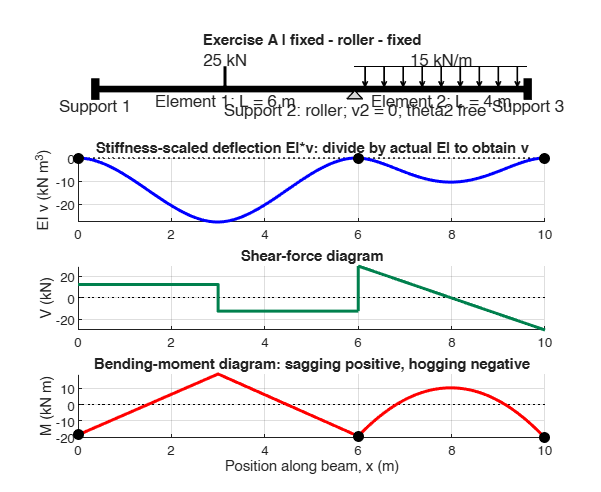

xlim(xNode([1 end])); xlabel('Position along beam, x (m)'); ylabel('M (kN m)');
title('Bending-moment diagram: sagging positive, hogging negative');